ur5 = loadrobot("universalUR5")

ur5 =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base_link'  'base'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'ee_link'  'tool0'}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'struct'


interface = "Gazebo"

interface = "Gazebo"

rosip = '192.168.1.1';
user = 'dtur5';
pass = 'DT_UR5';
ROSFolder = '/opt/ros/melodic';
WorkspaceFolder = '~/catkin_ws_quake';
ur5ip = '192.168.1.10';

device = rosdevice(rosip,user,pass)

device =   rosdevice with properties:

      DeviceAddress: '192.168.1.1'
           Username: 'dtur5'
     AvailableNodes: {0×1 cell}
          ROSFolder: '/opt/ros/noetic'
    CatkinWorkspace: '~/catkin_ws'


device.ROSFolder = ROSFolder

device =   rosdevice with properties:

      DeviceAddress: '192.168.1.1'
           Username: 'dtur5'
     AvailableNodes: {0×1 cell}
          ROSFolder: '/opt/ros/melodic'
    CatkinWorkspace: '~/catkin_ws'


% Check status of ROS core is running or not
if ~isCoreRunning(device)
 w = strsplit(system(device,'who'));
 displayNum = cell2mat(w(2));
 
 system(device,['export SVGA_VGPU10=0; ' ...
 'export DISPLAY=' displayNum '.0; ' ...
 './launchUR.sh &']);
pause(10);
end

ur = universalrobot(device.DeviceAddress,'RigidBodyTree',ur5)

Using user-defined rigid body tree model.


ur =   universalrobot with properties:

                  RigidBodyTree: [1×1 rigidBodyTree]
                JointStateTopic: '/joint_states'
    FollowJointTrajectoryAction: '/scaled_pos_joint_traj_controller/follow_joint_trajectory'
                 NumberOfJoints: 6
                EndEffectorName: 'tool0'


% Receive Joint angle range -pi to pi
jointTheta = getJointConfiguration(ur,10)

jointTheta =    -1.0251   -1.1908   -1.8259   -1.6965    1.5402   -0.2315



% Receive Cartesian Pose of End effector [θz θy θx X Y Z] [rad(θ) / m(axis)] (Joint 1-6 in order)
eepose = getCartesianPose(ur)

eepose =    -2.3643   -0.0296    3.1337    0.0738   -0.3367    0.4503



% Receive Joint angle velocity (rad/s)
jointVelo = getJointVelocity(ur)

jointVelo =      0     0     0     0     0     0



% Receive velocity of end effector [θ.z θ.y θ.x vX vY vZ] [rad/s(θ.) / m/s(axis)] (Joint 1-6 in order)
eeVelo = getEndEffectorVelocity(ur)

eeVelo =      0     0     0     0     0     0


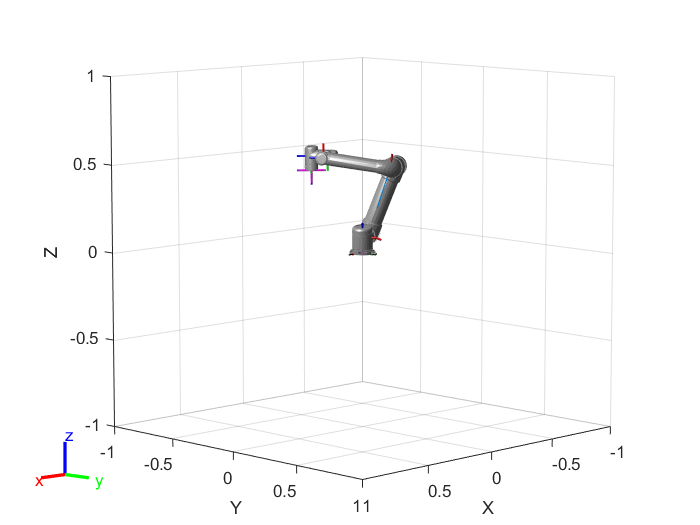


% Show model of UR5 at its current position
show(ur.RigidBodyTree,jointTheta);

% Move to desired position only once (range -pi to pi) by convert angle to radian
jointWaypoints = [-59.09 -68.54 -104.87 -97.34 87.99 -13.70]*pi/180; % Start 1,3,7,9
% jointWaypoints = [-59.00 -80.96 -138.74 -51.04 88.11 -14.20]*pi/180; % Step 2 & 8
% jointWaypoints = [-29.50 -90.86 -86.74 -93.63 88.46 15.78]*pi/180; % Step 4 & 6
% jointWaypoints = [-29.47 -102.58 -116.03 -52.62 88.58 15.30]*pi/180; % Step 5
[result,state] = sendJointConfigurationAndWait(ur,jointWaypoints,'EndTime',5)

result = logical
   1


state = 'succeeded'

joint_newTheta = getJointConfiguration(ur,10)

joint_newTheta =    -0.5143   -1.7904   -2.0251   -0.9184    1.5460    0.2670


eepose_new = getCartesianPose(ur)

eepose_new =    -2.3516   -0.0295    3.1274    0.3736   -0.3388    0.1749


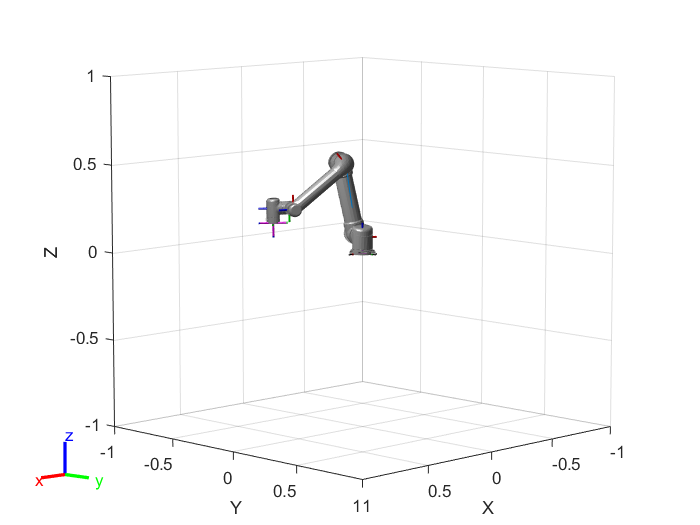

show(ur.RigidBodyTree,jointWaypoints);

% Set waypoint from start to desired position and move back to start
start_point = [-59.09 -68.54 -104.87 -97.34 87.99 -13.70]'*pi/180;
ur5.DataFormat = 'column'

ur5 =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base_link'  'base'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'ee_link'  'tool0'}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'column'


eeName = 'tool0'

eeName = 'tool0'

Trajec_start = getTransform(ur5, start_point, eeName);
Trajec_start(1:4,4) = [0;0;0;1]

Trajec_start =    -0.7112   -0.7021   -0.0368         0
   -0.7023    0.7118   -0.0068         0
    0.0310    0.0210   -0.9993         0
         0         0         0    1.0000



% Show UR5 model at start point 
show(ur5,start_point)

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


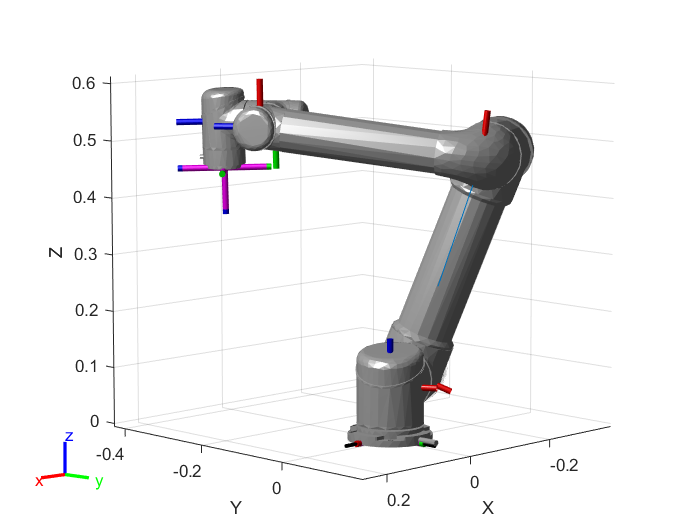

axis auto;

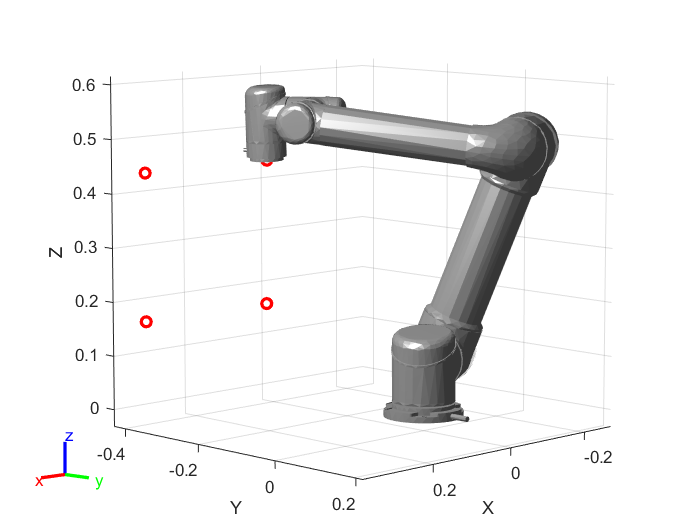


% Set waypoint from start position to desired position for plot waypoint
toolPositionHome = [0.0723   -0.3387    0.4462];
waypoints = toolPositionHome' + ...
            [0 0 0 ; +0.0011 -0.0006 -0.2713 ; +0.3004 -0.0001 0 ; +0.3013 -0.0001 -0.2713 ;  0 0 0]';

% Convert to Inverse Kinematics
ik = inverseKinematics('RigidBodyTree',ur5);
ikWeights = [1 1 1 1 1 1];
ikInitGuess = start_point';
ikInitGuess(ikInitGuess > pi) = ikInitGuess(ikInitGuess > pi) - 2*pi;
ikInitGuess(ikInitGuess < -pi) = ikInitGuess(ikInitGuess < -pi) + 2*pi;

% Set Plot of waypoint and display it
plotMode = 1; 
show(ur5,start_point,'Frames','off','PreservePlot',false);
hold on
if plotMode == 1 % Trajectory
    moving_path = plot3(waypoints(1,1),waypoints(2,1),waypoints(3,1),'b.-');
end
plot3(waypoints(1,:),waypoints(2,:),waypoints(3,:),'ro','LineWidth',2)
axis auto;

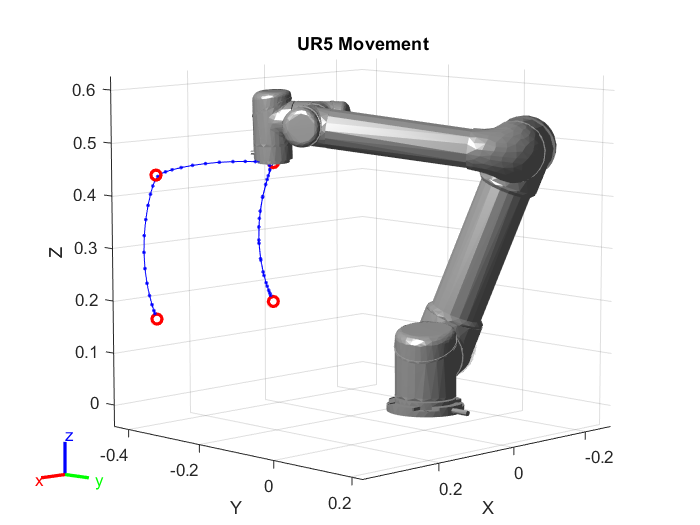

% Set the start waypoint to desired position, then move back to start
jointWaypoints2 = [-59.09 -68.54 -104.87 -97.34 87.99 -13.70; % Step 1
                   -59.09 -68.54 -104.87 -97.34 87.99 -13.70;
                   -59.00 -80.96 -138.74 -51.04 88.11 -14.20; % Step 2
                   -59.00 -80.96 -138.74 -51.04 88.11 -14.20;
                   -59.09 -68.54 -104.87 -97.34 87.99 -13.70; % Step 3
                   -59.09 -68.54 -104.87 -97.34 87.99 -13.70;
                   -29.50 -90.86 -86.74 -93.63 88.46 15.78;   % Step 4
                   -29.50 -90.86 -86.74 -93.63 88.46 15.78;
                   -29.47 -102.58 -116.03 -52.62 88.58 15.30; % Step 5
                   -29.47 -102.58 -116.03 -52.62 88.58 15.30;
                   -29.50 -90.86 -86.74 -93.63 88.46 15.78;   % Step 6
                   -29.50 -90.86 -86.74 -93.63 88.46 15.78;
                   -59.09 -68.54 -104.87 -97.34 87.99 -13.70; % Step 7
                   -59.09 -68.54 -104.87 -97.34 87.99 -13.70;
                   -59.00 -80.96 -138.74 -51.04 88.11 -14.20; % Step 8
                   -59.00 -80.96 -138.74 -51.04 88.11 -14.20;
                   -59.09 -68.54 -104.87 -97.34 87.99 -13.70; % Step 9
                   -59.09 -68.54 -104.87 -97.34 87.99 -13.70;]*pi/180;

wayPointTimes = 0:2:30;
trajTimes = linspace(0,wayPointTimes(end),100);
[q,qd,qdd] = bsplinepolytraj(jointWaypoints2',[0 wayPointTimes(end)],trajTimes);

followTrajectory(ur,q,qd,qdd,trajTimes);

% Plot the movement of UR5 with start point and desired position
for idx = 1:numel(trajTimes)  

    config = q(:,idx)';
    

    % Find Cartesian points for visualization
    eeTform = getTransform(ur5,config',eeName);
    if plotMode == 1 % Trajectory
        eePos = tform2trvec(eeTform);
        set(moving_path,'xdata',[moving_path.XData eePos(1)], ...
                  'ydata',[moving_path.YData eePos(2)], ...
                  'zdata',[moving_path.ZData eePos(3)]);
    elseif plotMode == 2 % Coordinates Frame
        plotTransforms(tform2trvec(eeTform),tform2quat(eeTform),'FrameSize',0.05);
    end

    % Show the robot
    show(ur5,config','Frames','off','PreservePlot',false);
    title('UR5 Movement')
    pause(0.25)
    drawnow
end
hold off


% Wait for the robot to complete the motion
[result2,~] = getMotionStatus(ur);
while ~result2
 [result2,~] = getMotionStatus(ur);
end